clear
syms theta(t) omega(t) [3,1] % omega = omega_BA is in basis A
% note that angular velocity is not expressed in body frame
syms q(t) [3,1] %[x;y;z] - Basis A
syms R m g I_s gamma real positive

P_IA = spinmat(1,gamma); % plane is rotated by gamma off vertical
% basis A is still inertial

% LMB:
syms F_p [3,1] real % basis A
F_B = P_IA'*[0;0;-m*g] + F_p == m*diff(q,t,t);

%AMB:
r_pg = [0;0;-R]; % basis A
I_Bg = I_s*eye(3); %any basis
M_Bg = cross(r_pg,F_p) == diff(I_Bg*omega,t);

%no slip contraint: v_po = v_pg + v_go = 0
v_po = cross(omega,r_pg) + diff(q,t) == 0;
a_po = diff(v_po,t);

clear r_go v_go a_go

syms q_dot_ omega_dot_ q_ddot_ [3,1] real
eqns = subs([F_B;M_Bg;a_po],[diff(q,t,t);diff(omega,t)], [q_ddot_;omega_dot_]);
eqns = subs(eqns,diff(q,t), q_dot_);
eqns = subs(eqns, [q;theta;omega], [sym('q',[3,1]);sym('theta',[3,1]);sym('omega',[3,1])]);

[A,f] = equationsToMatrix(simplify(eqns),[q_ddot_;omega_dot_;F_p]);
vars = [sym('q',[3,1]);sym('theta',[3,1]);q_dot_;sym('omega',[3,1])]

$$vars = \left[\begin{array}{c} q_{1}\\ q_{2}\\ q_{3}\\ \theta_{1}\\ \theta_{2}\\ \theta_{3}\\ {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ {\dot{q}}_{3}\\ \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right]$$


clearvars -except A f vars

## Substitute Variables

% dimensional parameters
R = 1;
m = 1;
gamma = 0.2; % inclination of hill

g = 9.8;

%initial conditions:
omega0 = [-3;1;0];

%simulation duration:
tf = 6;

%%%%%%%%
I_s = (2/5)*m*R^2;

r_go0 = [0;0;R];
theta0= [0;0;0];
v_go0 = cross(omega0,r_go0);

## Integrate:

hA = matlabFunction(subs(A),'Vars',{vars});
hf = matlabFunction(subs(f),'Vars',{vars});
% theta dot in terms of [theta;omega]:
hw = @(th,om) [1,0,-tan(th(2));0,1,0;0,0,sec(th(2))]*spinmat(1,-th(1))*om;

% z = [r_go; theta; v_go; omega]
function z_dot = EOM(z,hA,hf,hw)
u = hA(z)\hf(z);
z_dot = [z(7:9);
         hw(z(4:6),z(10:12));
         u(1:6)];
end

[t,z] = ode45(@(t,z)EOM(z,hA,hf,hw), linspace(0,tf,30*tf),[r_go0;theta0;v_go0;omega0]);
z=z';

## Animate:

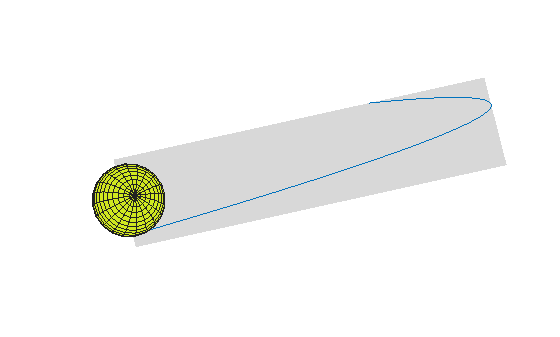

r_go = @(i) spinmat(1,gamma)*z(1:3,i);
r_po = @(i) spinmat(1,gamma)*(z(1:3,i)-[0;0;R]);

figure(1)
clf
hold on
constantplane([0;-sin(gamma);cos(gamma)],0)
traj = plot3(nan,nan,nan);

ball = hgtransform;
[a,b,c] = sphere;
surf(R*a,R*b,R*c,'FaceColor',rand(1,3),'Parent',ball);
axis equal off
view(85, 20)
for i = 1:length(t)
    set(ball,'Matrix',[spinmat([1,2,3],z([4,5,6],i)'),r_go(i);[0,0,0,1]])
    set(traj,'XData',[traj.XData,[1,0,0]*r_po(i)],'YData',[traj.YData,[0,1,0]*r_po(i)],'ZData',[traj.ZData,[0,0,1]*r_po(i)])
    drawnow
end

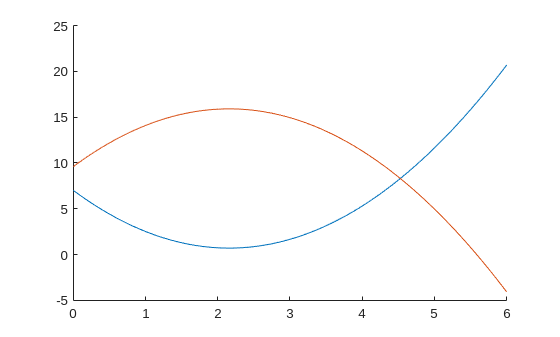

T_B = @(i) (1/2)*z(10:12,i)'*I_s*z(10:12,i) + (1/2)*m*z(7:9,i)'*z(7:9,i);
V_B = @(i) [0,0,m*g]*r_go(i);

figure(2)
clf
hold on
plot(t,arrayfun(T_B,1:length(t)),'DisplayName','Kinetic')
plot(t,arrayfun(V_B,1:length(t)),'DisplayName','Potential')

legend